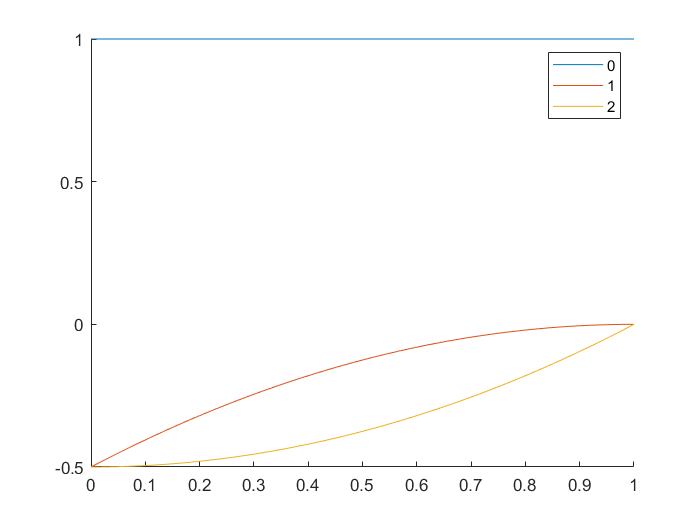

clear; 

syms h u t u0 u1 f0 f1

b0 = getPoly(t, 1, [1,0,0]');%[u1 f0 f1]
b1 = getPoly(t, 1, [0,1,0]');
b2 = getPoly(t, 1, [0,0,1]');
figure(1); clf;hold on;
fplot(b0,[0,1])
fplot(b1,[0,1])
fplot(b2,[0,1])
hold off;
legend('0','1','2');

## integration

syms alpha alpha2 v0 v1 v2
bases(t) = [1,t,t^2];
bases2(t) = [1,t,t^2,t^3]; % _2 is for 3rd degree poly integration
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

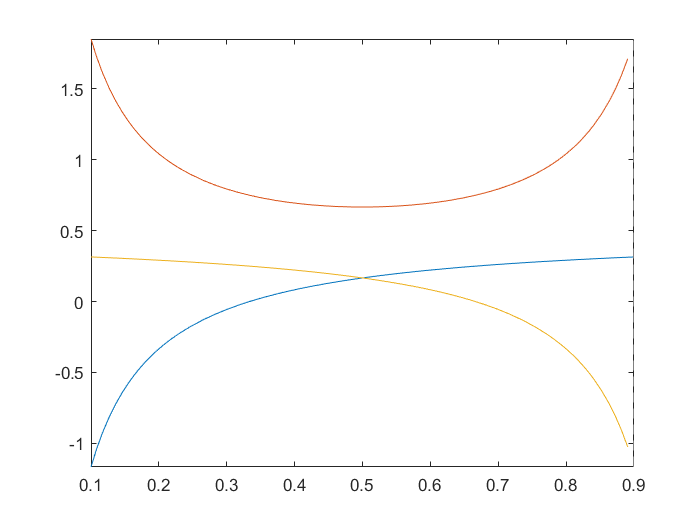

fplot(weights, [0.1,0.9])

weights2 = int(bases2 / ([bases2(0);bases2(alpha);bases2(alpha2); bases2(1)]),t,0,1)

$$weights2 = \begin{array}{l} \left(\begin{array}{cccc} \frac{\frac{\alpha }{2}-\frac{1}{6}}{\alpha }-\frac{\sigma_{1}}{\alpha \,\alpha_{2}} & \frac{2\,\alpha_{2}-1}{12\,\alpha \,\left(\alpha -\alpha_{2}\right)\,\left(\alpha -1\right)} & -\frac{2\,\alpha -1}{12\,\alpha_{2}\,\left(\alpha -\alpha_{2}\right)\,\left(\alpha_{2}-1\right)} & \frac{\frac{\alpha }{2}-\frac{1}{3}}{\alpha -1}+\frac{\sigma_{1}}{\left(\alpha -1\right)\,\left(\alpha_{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha }{6}-\frac{1}{12} \end{array}$$

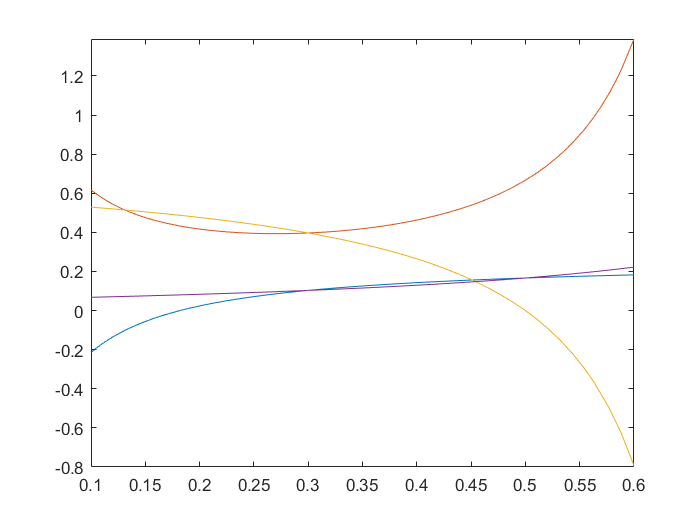

fplot(subs(weights2,alpha2,0.7), [0.1,0.6])

## input

u_mid = [b0(alpha),b1(alpha)*h,b2(alpha)*h] * transpose([u1,f0,f1])

$$u\_mid = u_{1}-f_{0}\,h\,\left(\frac{\alpha^{2}}{2}-\alpha +\frac{1}{2}\right)+f_{1}\,h\,\left(\frac{\alpha^{2}}{2}-\frac{1}{2}\right)$$

syms f_mid f_mid2;
incre = weights * [f0; f_mid; f1] * h;

## linear stability

syms lambda kappa
u_mid_lam = subs(u_mid, [f0,f1],[u0,u1] * lambda);

incre_lam = collect(subs(expand(incre), [f0,f_mid,f1], [u0*lambda,u_mid_lam*lambda,u1*lambda]), [u0,u1])

$$incre\_lam = \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }-\frac{h^{2}\,\lambda^{2}\,\left(\frac{\alpha^{2}}{2}-\alpha +\frac{1}{2}\right)}{\left(\alpha -\alpha^{2}\right)\,6}\right)\,u_{0}+\left(\frac{h\,\lambda }{2}+\frac{h\,\lambda }{6\,\left(\alpha -1\right)}+\frac{h\,\lambda \,\left(h\,\lambda \,\left(\frac{\alpha^{2}}{2}-\frac{1}{2}\right)+1\right)}{6\,\left(\alpha -\alpha^{2}\right)}\right)\,u_{1}$$

K = subs(simplify(solve(incre_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K = \frac{12\,\alpha -2\,\kappa +6\,\alpha \,\kappa +\alpha \,\kappa^{2}-\kappa^{2}}{12\,\alpha -2\,\kappa -6\,\alpha \,\kappa +\alpha \,\kappa^{2}+\kappa^{2}}$$

## stablility region

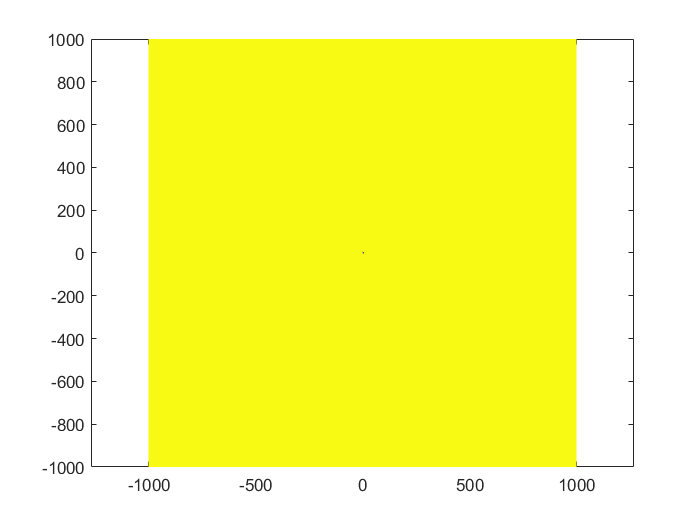

test_range = 1000;
rSamp = linspace(-test_range,test_range,1000);
iSamp = linspace(-test_range,test_range,1000);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa, alpha]));
alphatest = 0.9;
KM = abs(Kf(zSampM, alphatest));

p = pcolor(rSampM,iSampM, double(KM < 1));
p.EdgeColor = 'none';
axis equal;

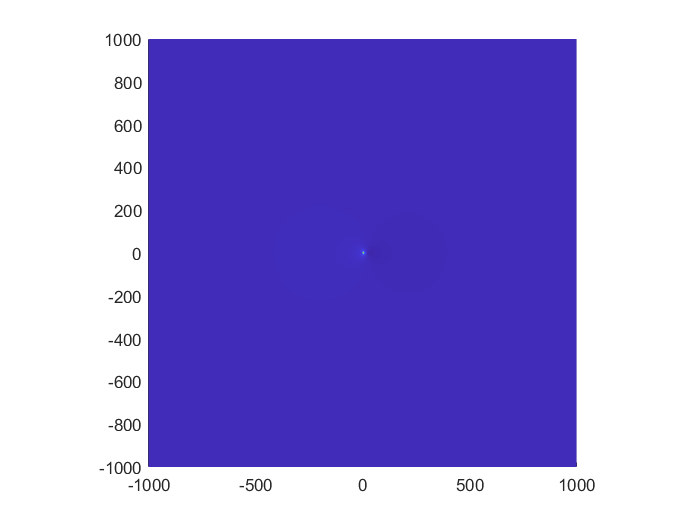

s = surf(rSampM,iSampM, double(min(KM,2)));
s.EdgeColor = 'none';
axis equal;
view(0,90)

function po = getPoly(t, h, cond) %[u1 f0 f1]
    bases(t) = [1,t,t^2];
    dB(t) = diff(bases,t);
    valBases = [bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end




